

I = imread('bellen.tif')

I = 256×256 uint8 matrix
   208   209   209   208   205   206   203   204   204   203   203   204   202   201   201   203   199   200   199   198   198   198   198   196   197   198   197   196   191   194   195   194   191   191   194   191   191   191   189   191   189   189   187   187   185   185   185   186   186   182
   210   211   209   206   206   208   204   204   204   204   203   202   204   204   203   203   200   202   200   198   198   199   198   201   199   197   196   197   195   192   192   193   193   194   193   192   190   190   192   189   190   188   187   185   187   186   185   187   185   185
   210   209   207   206   206   207   206   206   204   207   205   204   204   201   202   202   201   201   201   199   200   198   200   196   199   197   195   197   194   196   195   193   195   194   194   194   190   192   189   187   190   189   188   189   189   187   186   186   183   185
   209   210   209   211   208   207   209   208   205   206   205   204

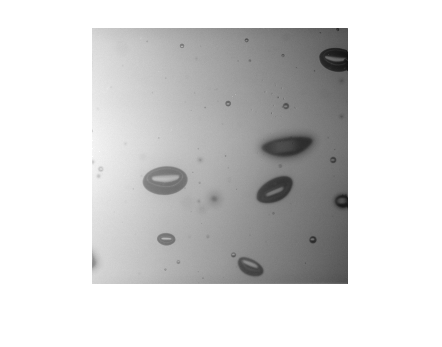

imshow(I)


tilesize = 100;
sampling = 50;
counter = 0;
size(I, 1)/sampling

ans = 5.1200

size(I, 1)/sampling + 1

ans = 6.1200

floor(size(I, 1)/sampling + 1)

ans = 6


tiles = zeros(floor(size(I,1)/sampling+1)*floor(size(I, 2) /sampling +1), 4)

tiles =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


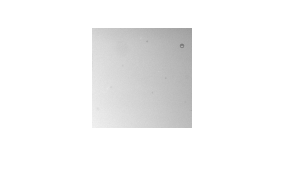


for x = 0:1:floor(size(I, 1)/sampling)
    for y = 0:1:floor(size(I, 2)/sampling)
        
        Xmin = x * sampling;
        Ymin = y * sampling;
        counter = counter + 1;
        
        tiles(counter, :) = [Xmin + 1, Ymin + 1, tilesize - 1, tilesize - 1];
    end
end
imcrop(I, tiles(1, :))

imshow(imcrop(I, tiles(1, :)))

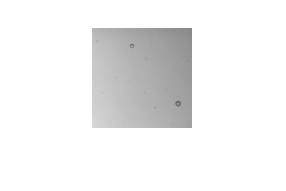

imshow(imcrop(I, tiles(7, :)))

treated_tiles = zeros([size(tiles, 1), tilesize, tilesize], 'uint8');
v_finalsize = size(imcrop(I, tiles(4, :)))

v_finalsize =    100   100


cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =     56   100


ENTREEE


Iout = 56×100 uint8 matrix
   222   224   220   221   217   221   220   219   218   217   218   215   216   216   216   215   216   216   215   215   216   212   212   212   211   211   210   211   208   209   209   209   209   207   207   207   206   203   206   204   203   201   203   204   203   201   200   200   199   199
   221   222   220   222   220   219   219   219   219   218   216   217   215   216   215   213   213   214   213   213   215   214   211   210   211   208   209   210   210   208   207   206   208   208   206   206   205   205   204   205   202   203   205   204   203   201   199   200   199   200
   221   220   220   221   220   220   220   220   221   216   219   216   216   215   216   214   212   215   214   215   212   212   212   212   211   210   209   207   209   209   209   208   206   207   206   207   207   205   203   203   206   201   202   202   201   203   199   200   200   202
   221   220   219   219   219   218   218   217   218   218   218   2

padding = 190

Iout = 100×100 uint8 matrix
   222   224   220   221   217   221   220   219   218   217   218   215   216   216   216   215   216   216   215   215   216   212   212   212   211   211   210   211   208   209   209   209   209   207   207   207   206   203   206   204   203   201   203   204   203   201   200   200   199   199
   221   222   220   222   220   219   219   219   219   218   216   217   215   216   215   213   213   214   213   213   215   214   211   210   211   208   209   210   210   208   207   206   208   208   206   206   205   205   204   205   202   203   205   204   203   201   199   200   199   200
   221   220   220   221   220   220   220   220   221   216   219   216   216   215   216   214   212   215   214   215   212   212   212   212   211   210   209   207   209   209   209   208   206   207   206   207   207   205   203   203   206   201   202   202   201   203   199   200   200   202
   221   220   219   219   219   218   218   217   218   218   218   

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =      6   100


ENTREEE


Iout = 6×100 uint8 matrix
   212   212   212   209   209   211   209   208   208   207   207   206   207   207   205   207   206   206   206   203   205   203   203   204   201   202   200   200   201   199   199   200   198   197   198   196   196   195   194   195   194   194   194   192   192   192   189   190   189   191
   212   213   211   210   211   212   209   209   208   208   209   206   208   205   207   206   205   203   204   205   204   201   202   203   201   200   202   199   201   200   197   197   200   198   197   197   194   193   194   193   197   193   192   195   193   193   190   191   192   190
   212   212   211   211   210   210   210   209   209   207   209   207   206   208   206   204   206   203   204   203   204   201   200   202   202   202   201   198   199   196   199   199   196   198   198   197   194   195   194   193   194   194   192   190   191   190   190   191   190   189
   210   209   210   211   209   209   209   209   208   205   207   20

padding = 188

Iout = 100×100 uint8 matrix
   212   212   212   209   209   211   209   208   208   207   207   206   207   207   205   207   206   206   206   203   205   203   203   204   201   202   200   200   201   199   199   200   198   197   198   196   196   195   194   195   194   194   194   192   192   192   189   190   189   191
   212   213   211   210   211   212   209   209   208   208   209   206   208   205   207   206   205   203   204   205   204   201   202   203   201   200   202   199   201   200   197   197   200   198   197   197   194   193   194   193   197   193   192   195   193   193   190   191   192   190
   212   212   211   211   210   210   210   209   209   207   209   207   206   208   206   204   206   203   204   203   204   201   200   202   202   202   201   198   199   196   199   199   196   198   198   197   194   195   194   193   194   194   192   190   191   190   190   191   190   189
   210   209   210   211   209   209   209   209   208   205   207   

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =     56   100


ENTREEE


Iout = 56×100 uint8 matrix
   198   199   194   197   196   196   194   195   192   194   192   192   191   192   191   189   189   187   187   187   187   185   187   185   184   184   183   184   181   183   183   179   179   179   178   179   178   178   178   177   176   174   175   174   177   174   174   173   175   173
   197   198   195   197   196   195   196   192   193   192   190   192   189   189   192   190   189   188   186   185   186   184   184   186   184   184   182   181   181   181   181   180   180   179   179   178   177   178   178   178   178   176   175   175   175   175   175   174   173   172
   200   198   197   198   196   194   194   194   193   190   191   191   191   190   189   190   189   187   186   185   187   185   185   183   182   182   181   181   181   182   180   180   179   179   178   177   177   176   177   177   177   177   175   175   177   175   174   175   174   172
   197   196   196   196   193   195   193   193   193   192   193   1

padding = 166

Iout = 100×100 uint8 matrix
   198   199   194   197   196   196   194   195   192   194   192   192   191   192   191   189   189   187   187   187   187   185   187   185   184   184   183   184   181   183   183   179   179   179   178   179   178   178   178   177   176   174   175   174   177   174   174   173   175   173
   197   198   195   197   196   195   196   192   193   192   190   192   189   189   192   190   189   188   186   185   186   184   184   186   184   184   182   181   181   181   181   180   180   179   179   178   177   178   178   178   178   176   175   175   175   175   175   174   173   172
   200   198   197   198   196   194   194   194   193   190   191   191   191   190   189   190   189   187   186   185   187   185   185   183   182   182   181   181   181   182   180   180   179   179   178   177   177   176   177   177   177   177   175   175   177   175   174   175   174   172
   197   196   196   196   193   195   193   193   193   192   193   

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =      6   100


ENTREEE


Iout = 6×100 uint8 matrix
   189   191   188   188   189   189   186   186   185   185   183   184   183   182   184   184   179   180   180   176   178   178   179   175   177   176   175   174   174   174   174   172   172   171   171   171   169   171   168   168   168   167   167   167   165   168   164   167   165   163
   192   188   188   188   189   187   186   186   185   186   185   184   183   182   180   180   181   180   181   178   180   177   176   175   174   176   173   174   174   175   174   170   173   172   170   168   170   170   167   165   167   168   166   167   164   165   163   166   162   162
   190   189   188   188   187   188   182   186   185   181   182   184   181   182   180   182   178   180   178   177   178   178   175   176   177   174   176   174   172   172   172   172   171   168   171   170   169   169   169   166   167   166   165   167   164   164   164   162   163   162
   187   187   187   188   187   187   185   184   183   183   181   18

padding = 162

Iout = 100×100 uint8 matrix
   189   191   188   188   189   189   186   186   185   185   183   184   183   182   184   184   179   180   180   176   178   178   179   175   177   176   175   174   174   174   174   172   172   171   171   171   169   171   168   168   168   167   167   167   165   168   164   167   165   163
   192   188   188   188   189   187   186   186   185   186   185   184   183   182   180   180   181   180   181   178   180   177   176   175   174   176   173   174   174   175   174   170   173   172   170   168   170   170   167   165   167   168   166   167   164   165   163   166   162   162
   190   189   188   188   187   188   182   186   185   181   182   184   181   182   180   182   178   180   178   177   178   178   175   176   177   174   176   174   172   172   172   172   171   168   171   170   169   169   169   166   167   166   165   167   164   164   164   162   163   162
   187   187   187   188   187   187   185   184   183   183   181   

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =     56   100


ENTREEE


Iout = 56×100 uint8 matrix
   171   171   173   173   171   168   169   170   168   168   168   168   165   165   167   163   165   163   165   163   165   163   163   161   163   161   161   160   157   159   158   158   157   156   155   156   154   155   155   153   154   153   152   150   153   149   148   147   149   149
   173   171   172   171   168   170   168   169   170   168   167   167   167   166   165   164   164   164   165   165   163   162   162   162   162   162   161   161   157   159   158   157   157   157   155   155   155   153   153   152   152   154   150   151   150   148   148   149   147   148
   172   171   171   172   171   168   169   166   168   166   165   166   165   166   162   164   164   164   163   162   162   164   163   160   162   159   159   160   158   157   158   156   157   155   155   154   155   153   154   151   152   152   153   149   151   150   147   149   148   146
   171   171   172   169   172   170   169   167   171   169   166   1

padding = 139

Iout = 100×100 uint8 matrix
   171   171   173   173   171   168   169   170   168   168   168   168   165   165   167   163   165   163   165   163   165   163   163   161   163   161   161   160   157   159   158   158   157   156   155   156   154   155   155   153   154   153   152   150   153   149   148   147   149   149
   173   171   172   171   168   170   168   169   170   168   167   167   167   166   165   164   164   164   165   165   163   162   162   162   162   162   161   161   157   159   158   157   157   157   155   155   155   153   153   152   152   154   150   151   150   148   148   149   147   148
   172   171   171   172   171   168   169   166   168   166   165   166   165   166   162   164   164   164   163   162   162   164   163   160   162   159   159   160   158   157   158   156   157   155   155   154   155   153   154   151   152   152   153   149   151   150   147   149   148   146
   171   171   172   169   172   170   169   167   171   169   166   

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =      6   100


ENTREEE


Iout = 6×100 uint8 matrix
   163   162   163   162   161   161   159   158   158   158   139   140   155   157   156   155   154   156   151   152   152   152   151   151   150   148   149   152   149   147   146   146   146   145   145   144   147   144   142   143   140   142   142   138   141   139   137   137   136   138
   160   161   163   160   158   159   158   159   157   157   157   157   154   157   155   153   154   152   153   153   152   149   152   152   150   149   149   146   147   147   145   146   143   145   142   143   144   141   141   143   138   139   139   139   139   138   136   136   137   137
   161   161   161   162   157   160   159   158   157   158   157   155   155   153   155   153   152   151   149   151   152   153   150   151   151   151   149   150   146   147   146   144   145   144   144   146   142   142   142   141   141   141   140   138   141   138   137   137   138   136
   161   160   161   159   158   156   158   156   157   155   157   15

padding = 136

Iout = 100×100 uint8 matrix
   163   162   163   162   161   161   159   158   158   158   139   140   155   157   156   155   154   156   151   152   152   152   151   151   150   148   149   152   149   147   146   146   146   145   145   144   147   144   142   143   140   142   142   138   141   139   137   137   136   138
   160   161   163   160   158   159   158   159   157   157   157   157   154   157   155   153   154   152   153   153   152   149   152   152   150   149   149   146   147   147   145   146   143   145   142   143   144   141   141   143   138   139   139   139   139   138   136   136   137   137
   161   161   161   162   157   160   159   158   157   158   157   155   155   153   155   153   152   151   149   151   152   153   150   151   151   151   149   150   146   147   146   144   145   144   144   146   142   142   142   141   141   141   140   138   141   138   137   137   138   136
   161   160   161   159   158   156   158   156   157   155   157   

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100   100


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =     56   100


ENTREEE


Iout = 56×100 uint8 matrix
   146   146   147   146   145   145   144   140   139   143   142   141   142   140   143   138   140   139   138   138   137   137   134   133   137   136   134   134   132   131   133   132   131   131   130   129   128   128   128   128   127   126   126   126   127   125   124   124   124   123
   148   145   147   143   145   144   144   145   144   144   141   141   142   141   141   139   139   139   139   138   137   135   136   136   134   135   134   132   135   131   131   130   132   130   131   129   129   128   129   128   128   128   126   125   125   125   123   124   123   121
   148   147   146   145   144   144   144   141   143   140   142   141   141   139   138   139   139   138   138   137   139   136   135   134   135   134   136   133   132   132   131   132   131   130   130   129   128   130   128   127   126   125   125   124   126   125   122   125   124   123
   146   146   146   145   144   143   145   141   144   140   143   1

padding = 114

Iout = 100×100 uint8 matrix
   146   146   147   146   145   145   144   140   139   143   142   141   142   140   143   138   140   139   138   138   137   137   134   133   137   136   134   134   132   131   133   132   131   131   130   129   128   128   128   128   127   126   126   126   127   125   124   124   124   123
   148   145   147   143   145   144   144   145   144   144   141   141   142   141   141   139   139   139   139   138   137   135   136   136   134   135   134   132   135   131   131   130   132   130   131   129   129   128   129   128   128   128   126   125   125   125   123   124   123   121
   148   147   146   145   144   144   144   141   143   140   142   141   141   139   138   139   139   138   138   137   139   136   135   134   135   134   136   133   132   132   131   132   131   130   130   129   128   130   128   127   126   125   125   124   126   125   122   125   124   123
   146   146   146   145   144   143   145   141   144   140   143   

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =      6   100


ENTREEE


Iout = 6×100 uint8 matrix
   136   136   135   133   132   132   132   130   128   130   129   127   127   126   125   125   125   127   126   126   125   125   125   122   122   122   124   123   121   122   120   120   119   120   116   117   116   115   116   116   116   116   115   114   115   113   113   112   113   111
   135   135   135   134   133   130   132   130   129   129   129   128   128   127   128   125   126   125   125   123   126   123   124   124   120   120   122   121   121   117   121   120   118   117   117   116   115   117   113   116   115   114   114   113   112   112   112   110   113   112
   134   135   132   131   132   130   131   133   130   127   129   127   127   126   127   125   127   124   121   123   125   124   123   122   121   123   122   120   121   118   118   119   118   117   117   117   119   117   114   115   115   113   113   113   112   110   111   110   110   110
   133   133   134   132   133   131   132   130   129   129   129   12

padding = 111

Iout = 100×100 uint8 matrix
   136   136   135   133   132   132   132   130   128   130   129   127   127   126   125   125   125   127   126   126   125   125   125   122   122   122   124   123   121   122   120   120   119   120   116   117   116   115   116   116   116   116   115   114   115   113   113   112   113   111
   135   135   135   134   133   130   132   130   129   129   129   128   128   127   128   125   126   125   125   123   126   123   124   124   120   120   122   121   121   117   121   120   118   117   117   116   115   117   113   116   115   114   114   113   112   112   112   110   113   112
   134   135   132   131   132   130   131   133   130   127   129   127   127   126   127   125   127   124   121   123   125   124   123   122   121   123   122   120   121   118   118   119   118   117   117   117   119   117   114   115   115   113   113   113   112   110   111   110   110   110
   133   133   134   132   133   131   132   130   129   129   129   

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100    56


ENTREEE


Iout = 100×56 uint8 matrix
   110   108   108   105   105   106   105   103   104   105   103   104   104   102   104   102   101   100    98    97    98    97    98    94    97    95    96    95    94    92    96    93    93    93    91    92    90    91    91    89    86    89    87    89    65    44    53    84    84    85
   111   108   109   108   107   105   105   109   105   103   103   104   104   103   103   104    98    99   101    99   100    96    97    96    99    96    94    97    96    94    94    92    93    91    91    91    92    91    90    91    89    88    89    88    60    59    42    79    84    84
   110   109   109   110   108   108   108   109   108   105   104   106   105   105   102   102   101   100    99   100   100    98    97    96    97    97    95    96    98    96    96    94    95    94    95    94    93    93    89    91    89    89    91    89    81    60    51    85    85    84
   111   112   112   111   109   107   109   105   107   106   107   1

padding = 106

Iout = 100×100 uint8 matrix
   110   108   108   105   105   106   105   103   104   105   103   104   104   102   104   102   101   100    98    97    98    97    98    94    97    95    96    95    94    92    96    93    93    93    91    92    90    91    91    89    86    89    87    89    65    44    53    84    84    85
   111   108   109   108   107   105   105   109   105   103   103   104   104   103   103   104    98    99   101    99   100    96    97    96    99    96    94    97    96    94    94    92    93    91    91    91    92    91    90    91    89    88    89    88    60    59    42    79    84    84
   110   109   109   110   108   108   108   109   108   105   104   106   105   105   102   102   101   100    99   100   100    98    97    96    97    97    95    96    98    96    96    94    95    94    95    94    93    93    89    91    89    89    91    89    81    60    51    85    85    84
   111   112   112   111   109   107   109   105   107   106   107   

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100    56


ENTREEE


Iout = 100×56 uint8 matrix
   129   128   127   125   126   127   126   125   122   124   122   122   123   120   122   118   118   117   117   116   116   114   117   115   115   114   114   111   113   110   110   111   110   110   108   106   107   107   106   107   105   105   104   100   103   100    98    97    93    94
   128   128   127   126   126   128   126   124   123   123   123   121   122   121   119   118   120   119   118   118   117   117   116   117   116   115   114   115   114   110   114   111   111   111   112   108   108   108   108   105   105   104   105   103   102   102    99    94    92    87
   129   127   127   127   126   123   124   124   123   124   122   123   122   121   120   119   120   118   118   118   117   114   114   116   115   114   112   115   113   112   110   110   111   109   108   108   107   107   109   105   106   103   106   104   103   100    96    93    88    81
   130   128   131   126   126   125   125   125   124   125   124   1

padding = 114

Iout = 100×100 uint8 matrix
   129   128   127   125   126   127   126   125   122   124   122   122   123   120   122   118   118   117   117   116   116   114   117   115   115   114   114   111   113   110   110   111   110   110   108   106   107   107   106   107   105   105   104   100   103   100    98    97    93    94
   128   128   127   126   126   128   126   124   123   123   123   121   122   121   119   118   120   119   118   118   117   117   116   117   116   115   114   115   114   110   114   111   111   111   112   108   108   108   108   105   105   104   105   103   102   102    99    94    92    87
   129   127   127   127   126   123   124   124   123   124   122   123   122   121   120   119   120   118   118   118   117   114   114   116   115   114   112   115   113   112   110   110   111   109   108   108   107   107   109   105   106   103   106   104   103   100    96    93    88    81
   130   128   131   126   126   125   125   125   124   125   124   

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100    56


ENTREEE


Iout = 100×56 uint8 matrix
   132   130   130   130   128   131   130   129   127   127   126   126   125   127   126   124   126   125   125   126   125   126   124   123   125   126   123   124   123   122   122   122   123   121   120   122   119   118   119   119   118   118   117   117   118   117   115   115   115   114
   131   128   129   127   126   127   125   125   127   125   125   124   124   124   121   124   123   124   121   126   123   125   124   124   123   122   124   125   123   123   124   122   122   120   120   118   119   120   119   118   119   115   118   117   117   115   115   116   112   114
   129   126   126   122   128   125   122   123   123   121   121   123   122   121   121   123   121   120   120   121   122   124   123   122   123   125   125   124   123   123   123   120   121   121   121   120   117   120   120   118   118   118   117   116   117   116   115   116   115   114
   124   122   124   121   122   121   121   119   118   120   119   1

padding = 109

Iout = 100×100 uint8 matrix
   132   130   130   130   128   131   130   129   127   127   126   126   125   127   126   124   126   125   125   126   125   126   124   123   125   126   123   124   123   122
   131   128   129   127   126   127   125   125   127   125   125   124   124   124   121   124   123   124   121   126   123   125   124   124   123   122   124   125   123   123
   129   126   126   122   128   125   122   123   123   121   121   123   122   121   121   123   121   120   120   121   122   124   123   122   123   125   125   124   123   123
   124   122   124   121   122   121   121   119   118   120   119   120   119   119   117   118   119   121   120   120   121   118   123   121   123   123   123   121   124   122
   122   119   119   119   117   115   117   116   114   116   115   113   115   115   114   115   114   117   116   118   118   118   121   122   122   122   120   124   120   122
   115   115   114   115   113   112   111   111   110   111   111 

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100    56


ENTREEE


Iout = 100×56 uint8 matrix
   116   123   126   128   126   126   126   127   126   125   127   124   125   124   125   125   125   124   123   123   123   121   122   120   120   121   118   120   118   119
   107   119   127   126   126   127   127   125   125   124   125   125   124   123   124   124   123   123   123   121   124   120   119   121   121   119   117   118   118   120
    96   113   124   125   126   126   125   126   125   126   124   125   126   126   125   124   123   123   122   123   123   123   121   121   119   120   118   120   118   117
    85   111   123   124   128   127   125   125   125   126   125   123   123   123   124   121   124   122   122   124   122   122   121   120   120   118   118   118   117   117
    81   109   119   124   125   125   124   125   125   125   125   124   123   125   123   125   122   125   122   120   121   120   120   120   118   120   119   118   118   116
    80   109   121   125   125   123   125   125   124   125   126  

padding = 106

Iout = 100×100 uint8 matrix
   116   123   126   128   126   126   126   127   126   125   127   124   125   124   125   125   125   124   123   123   123   121   122   120   120   121   118   120   118   119
   107   119   127   126   126   127   127   125   125   124   125   125   124   123   124   124   123   123   123   121   124   120   119   121   121   119   117   118   118   120
    96   113   124   125   126   126   125   126   125   126   124   125   126   126   125   124   123   123   122   123   123   123   121   121   119   120   118   120   118   117
    85   111   123   124   128   127   125   125   125   126   125   123   123   123   124   121   124   122   122   124   122   122   121   120   120   118   118   118   117   117
    81   109   119   124   125   125   124   125   125   125   125   124   123   125   123   125   122   125   122   120   121   120   120   120   118   120   119   118   118   116
    80   109   121   125   125   123   125   125   124   125   126 

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =     56    56


ENTREEE


Iout = 56×56 uint8 matrix
   122   122   122   121   121   121   120   119   117   117   120   118   117   115   115   115   115   114   114   114   111   111   113   111   111   111   110   108   108   107
   122   123   123   121   120   120   121   118   119   118   119   116   116   116   117   116   115   113   112   113   112   113   111   112   111   109   110   108   108   110
   122   121   121   119   119   120   120   120   117   119   116   117   116   117   116   114   115   113   113   113   110   111   112   110   109   110   108   107   107   109
   122   122   122   121   121   118   119   120   116   119   117   116   114   116   115   115   114   112   113   111   112   110   110   109   109   109   107   110   107   107
   122   120   122   119   119   119   119   117   117   119   118   115   117   115   114   113   113   112   110   109   111   110   111   109   108   110   109   108   108   108
   120   122   119   119   119   117   117   118   119   117   117   

padding = 102

Iout = 100×100 uint8 matrix
   122   122   122   121   121   121   120   119   117   117   120   118   117   115   115   115   115   114   114   114   111   111   113   111   111   111   110   108   108   107
   122   123   123   121   120   120   121   118   119   118   119   116   116   116   117   116   115   113   112   113   112   113   111   112   111   109   110   108   108   110
   122   121   121   119   119   120   120   120   117   119   116   117   116   117   116   114   115   113   113   113   110   111   112   110   109   110   108   107   107   109
   122   122   122   121   121   118   119   120   116   119   117   116   114   116   115   115   114   112   113   111   112   110   110   109   109   109   107   110   107   107
   122   120   122   119   119   119   119   117   117   119   118   115   117   115   114   113   113   112   110   109   111   110   111   109   108   110   109   108   108   108
   120   122   119   119   119   117   117   118   119   117   117 

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =      6    56


ENTREEE


Iout = 6×56 uint8 matrix
   110   111   108   108   110   106   106   105   106   108   106   104   104   104   102   102   102   101   101    99    99    99   100    97    96    97    99    94    95    92
   110   111   108   107   107   108   108   106   104   104   106   104   104   104   103   101   104   101   103   101   100    99    94    98    96    97    96    95    94    94
   109   110   108   107   108   106   107   106   106   106   103   105   104   103   102   101   102   102   101   101    99   102    97    98    94    96    94    96    93    93
   110   110   110   106   110   105   105   104   104   106   104   105   103   103   102   102   102   100   100    99    97    99    97    97    96    94    95    94    93    93
   111   111   110   109   109   109   108   110   107   108   106   105   106   105   104   103   105   104   102   103   100   101   101   101    99    99    98    99    96    97
   120   119   117   119   120   120   117   116   115   116   117   1

padding = 97

Iout = 100×100 uint8 matrix
   110   111   108   108   110   106   106   105   106   108   106   104   104   104   102   102   102   101   101    99    99    99   100    97    96    97    99    94    95    92
   110   111   108   107   107   108   108   106   104   104   106   104   104   104   103   101   104   101   103   101   100    99    94    98    96    97    96    95    94    94
   109   110   108   107   108   106   107   106   106   106   103   105   104   103   102   101   102   102   101   101    99   102    97    98    94    96    94    96    93    93
   110   110   110   106   110   105   105   104   104   106   104   105   103   103   102   102   102   100   100    99    97    99    97    97    96    94    95    94    93    93
   111   111   110   109   109   109   108   110   107   108   106   105   106   105   104   103   105   104   102   103   100   101   101   101    99    99    98    99    96    97
   120   119   117   119   120   120   117   116   115   116   117 

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100     6


ENTREEE


Iout = 100×6 uint8 matrix
   84   84   82   83   83   99
   87   85   87   83   84   83
   85   86   86   84   83   81
   87   84   84   84   84   83
   86   84   86   84   87   84
   87   87   88   88   85   86
   89   87   88   86   87   85
   89   88   88   87   87   84
   88   87   88   88   87   86
   91   88   88   87   87   84


padding = 85

Iout = 100×100 uint8 matrix
   84   84   82   83   83   99   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85
   87   85   87   83   84   83   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85
   85   86   86   84   83   81   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85
   87   84   84   84   84   83   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85
   86   84   86   84   87   84   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85
   87   87   88   88   85   86   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85   85
   89   87   88   86   87   85   85   85   85   85   85   85   85 

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100     6


ENTREEE


Iout = 100×6 uint8 matrix
    90    94    95    97    96    97
    88    91    94    96    96    95
    82    90    95    96    97    96
    87    90    94    99   100    97
    92    94    95    97    98    99
    94    96    98   100   100    98
    97    99    99   100    99    99
   102   100   102   100    99    98
   103   102   101   101   102   101
   102   102   101   103   101   100


padding = 108

Iout = 100×100 uint8 matrix
    90    94    95    97    96    97   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108
    88    91    94    96    96    95   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108
    82    90    95    96    97    96   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108
    87    90    94    99   100    97   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108
    92    94    95    97    98    99   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108   108
    94    96    98   100   100    98   108   108   108   108   108 

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100     6


ENTREEE


Iout = 100×6 uint8 matrix
   112   115   113   111   111   111
   112   113   115   113   111   110
   114   113   111   113   112   112
   113   115   113   112   114   112
   114   114   112   110   112   109
   113   113   113   111   111   111
   113   114   113   110   112   112
   116   111   112   112   113   111
   114   112   114   111   112   111
   112   112   111   111   112   111


padding = 97

Iout = 100×100 uint8 matrix
   112   115   113   111   111   111    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97
   112   113   115   113   111   110    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97
   114   113   111   113   112   112    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97
   113   115   113   112   114   112    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97
   114   114   112   110   112   109    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97    97
   113   113   113   111   111   111    97    97    97    97    97 

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =    100     6


ENTREEE


Iout = 100×6 uint8 matrix
   107   106   106   106   105   104
   108   106   105   105   104   106
   107   108   106   106   102   105
   106   108   105   105   104   105
   105   105   105   105   104   105
   105   106   106   106   105   101
   106   105   103   102   103   104
   105   102   104   102   102   102
   104   104   103   102   102   101
   103   104   103   103   102   102


padding = 86

Iout = 100×100 uint8 matrix
   107   106   106   106   105   104    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86
   108   106   105   105   104   106    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86
   107   108   106   106   102   105    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86
   106   108   105   105   104   105    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86
   105   105   105   105   104   105    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86    86
   105   106   106   106   105   101    86    86    86    86    86 

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =     56     6


ENTREEE


Iout = 56×6 uint8 matrix
   95   95   94   94   92   94
   96   95   95   94   94   93
   94   96   95   95   93   94
   96   96   94   92   92   92
   95   93   94   93   95   94
   93   94   92   94   93   93
   93   94   92   91   92   92
   93   93   94   92   90   92
   94   93   92   91   93   90
   95   93   91   90   91   93


padding = 89

Iout = 100×100 uint8 matrix
   95   95   94   94   92   94   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89
   96   95   95   94   94   93   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89
   94   96   95   95   93   94   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89
   96   96   94   92   92   92   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89
   95   93   94   93   95   94   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89
   93   94   92   94   93   93   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89   89
   93   94   92   91   92   92   89   89   89   89   89   89   89 

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

cosa =      6     6


ENTREEE


Iout = 6×6 uint8 matrix
   82   82   80   78   78   83
   83   81   79   80   78   78
   83   81   81   79   80   79
   81   80   80   80   79   79
   87   84   86   84   84   78
   98   99   98   97   98   85


padding = 83

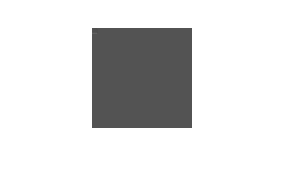

Iout = 100×100 uint8 matrix
   82   82   80   78   78   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   83   81   79   80   78   78   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   83   81   81   79   80   79   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   81   80   80   80   79   79   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   87   84   86   84   84   78   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   98   99   98   97   98   85   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   83   83   83   83   83   83   83   83   83   83   83   83   83 

SALIII


treated_tiles = 36×100×100 uint8 array
treated_tiles(:,:,1) =

   208   210   210   209   212   210   213   215   213   216   215   215   217   218   219   220   220   219   222   220   219   223   222   220   222   219   217   218   216   220   218   220   225   218   219   216   220   220   218   222   226   221   224   226   228   227   228   227   227   226   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239
   228   228   230   229   230   230   231   227   232   229   231   232   233   231   232   230   228   230   231   230   231   233   231   233   233   233   232   233   234   235   234   235   234   237   235   235   235   237   236   238   238   239   239   239   234   239   238   239   241   239   239   228   212   211   234   240

ans = 'recrop_251  251   99   99.tif'

for i = 1:size(tiles, 1)
    %i %tst
    %tiles(i, :) %tst
    Iout = imcrop(I, tiles(i, :));
    imshow(Iout);
    cosa =size(Iout)
    if ~isequal(size(Iout), v_finalsize)
        disp('ENTREEE')
        Iout
        padding = round(mean(mean(Iout)))
        Itmp = zeros(v_finalsize, 'uint8');
        for x = 1:1:tilesize
            for y = 1:1:tilesize
                if x > size(Iout, 1) || y > size(Iout, 2)
                    Itmp(x, y) = padding;
                else
                    Itmp(x, y) = Iout(x, y);
                end    
            end
        end
        imshow(Itmp)
        Iout = Itmp
        
        disp('SALIII')
    end
    treated_tiles(i, :, :) = Iout
    %imshow(Iout)
    
    strcat(strcat('recrop_', num2str(tiles(counter, :))), '.tif')
    %imwrite(Iout, strcat(strcat('recrop_', num2str(tiles(counter, :))), '.tif'))    

end

%imshow(shape(treated_tiles(1,  : , :), )
tiles(2)

ans = 1